clc
clear
close all 

b = 50;
m = 1000;
tau_p = m/b;

num_p = 1;
den_p = b*[tau_p 1];

P = tf(num_p,den_p)


P =
 
       1
  -----------
  1000 s + 50
 
Continuous-time transfer function.
Model Properties


step(500*P);
grid on;
hold on

Tr = 20; % Tempo di salita [s].
Wc = 5/Tr; % Omega critica [rad/s].
Ki = Wc*b; % Ki.
Kp = tau_p*Ki % Kp.

Kp = 250

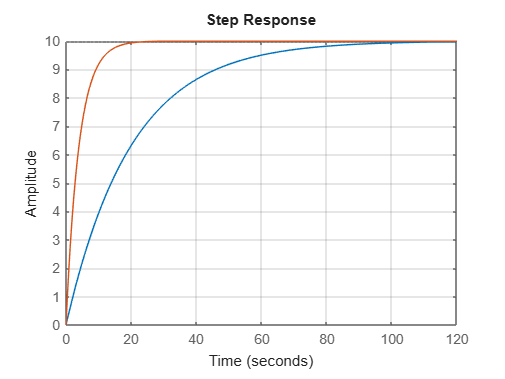


C = pid(Kp,Ki); % Controllore PI.

L = C*P; % Sistema ad anello aperto.

W = feedback(L,1); % Sistema ad anello chiuso.

% t = 0:0.1:20;
step(10*W);
grid on;
hold off

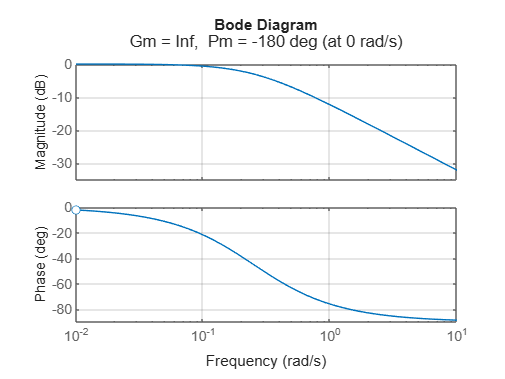


margin(W);
grid on;

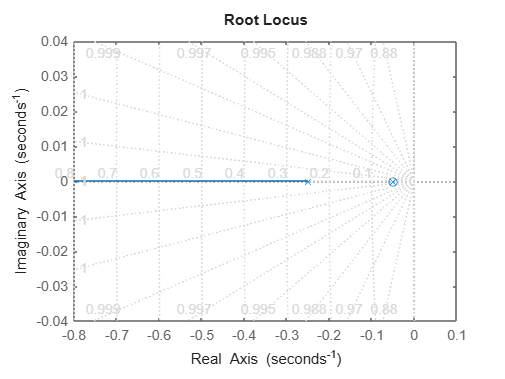


rlocus(W)
grid on;


pole(W)

ans =    -0.2500
   -0.0500
